## 1. Завантаження зображень

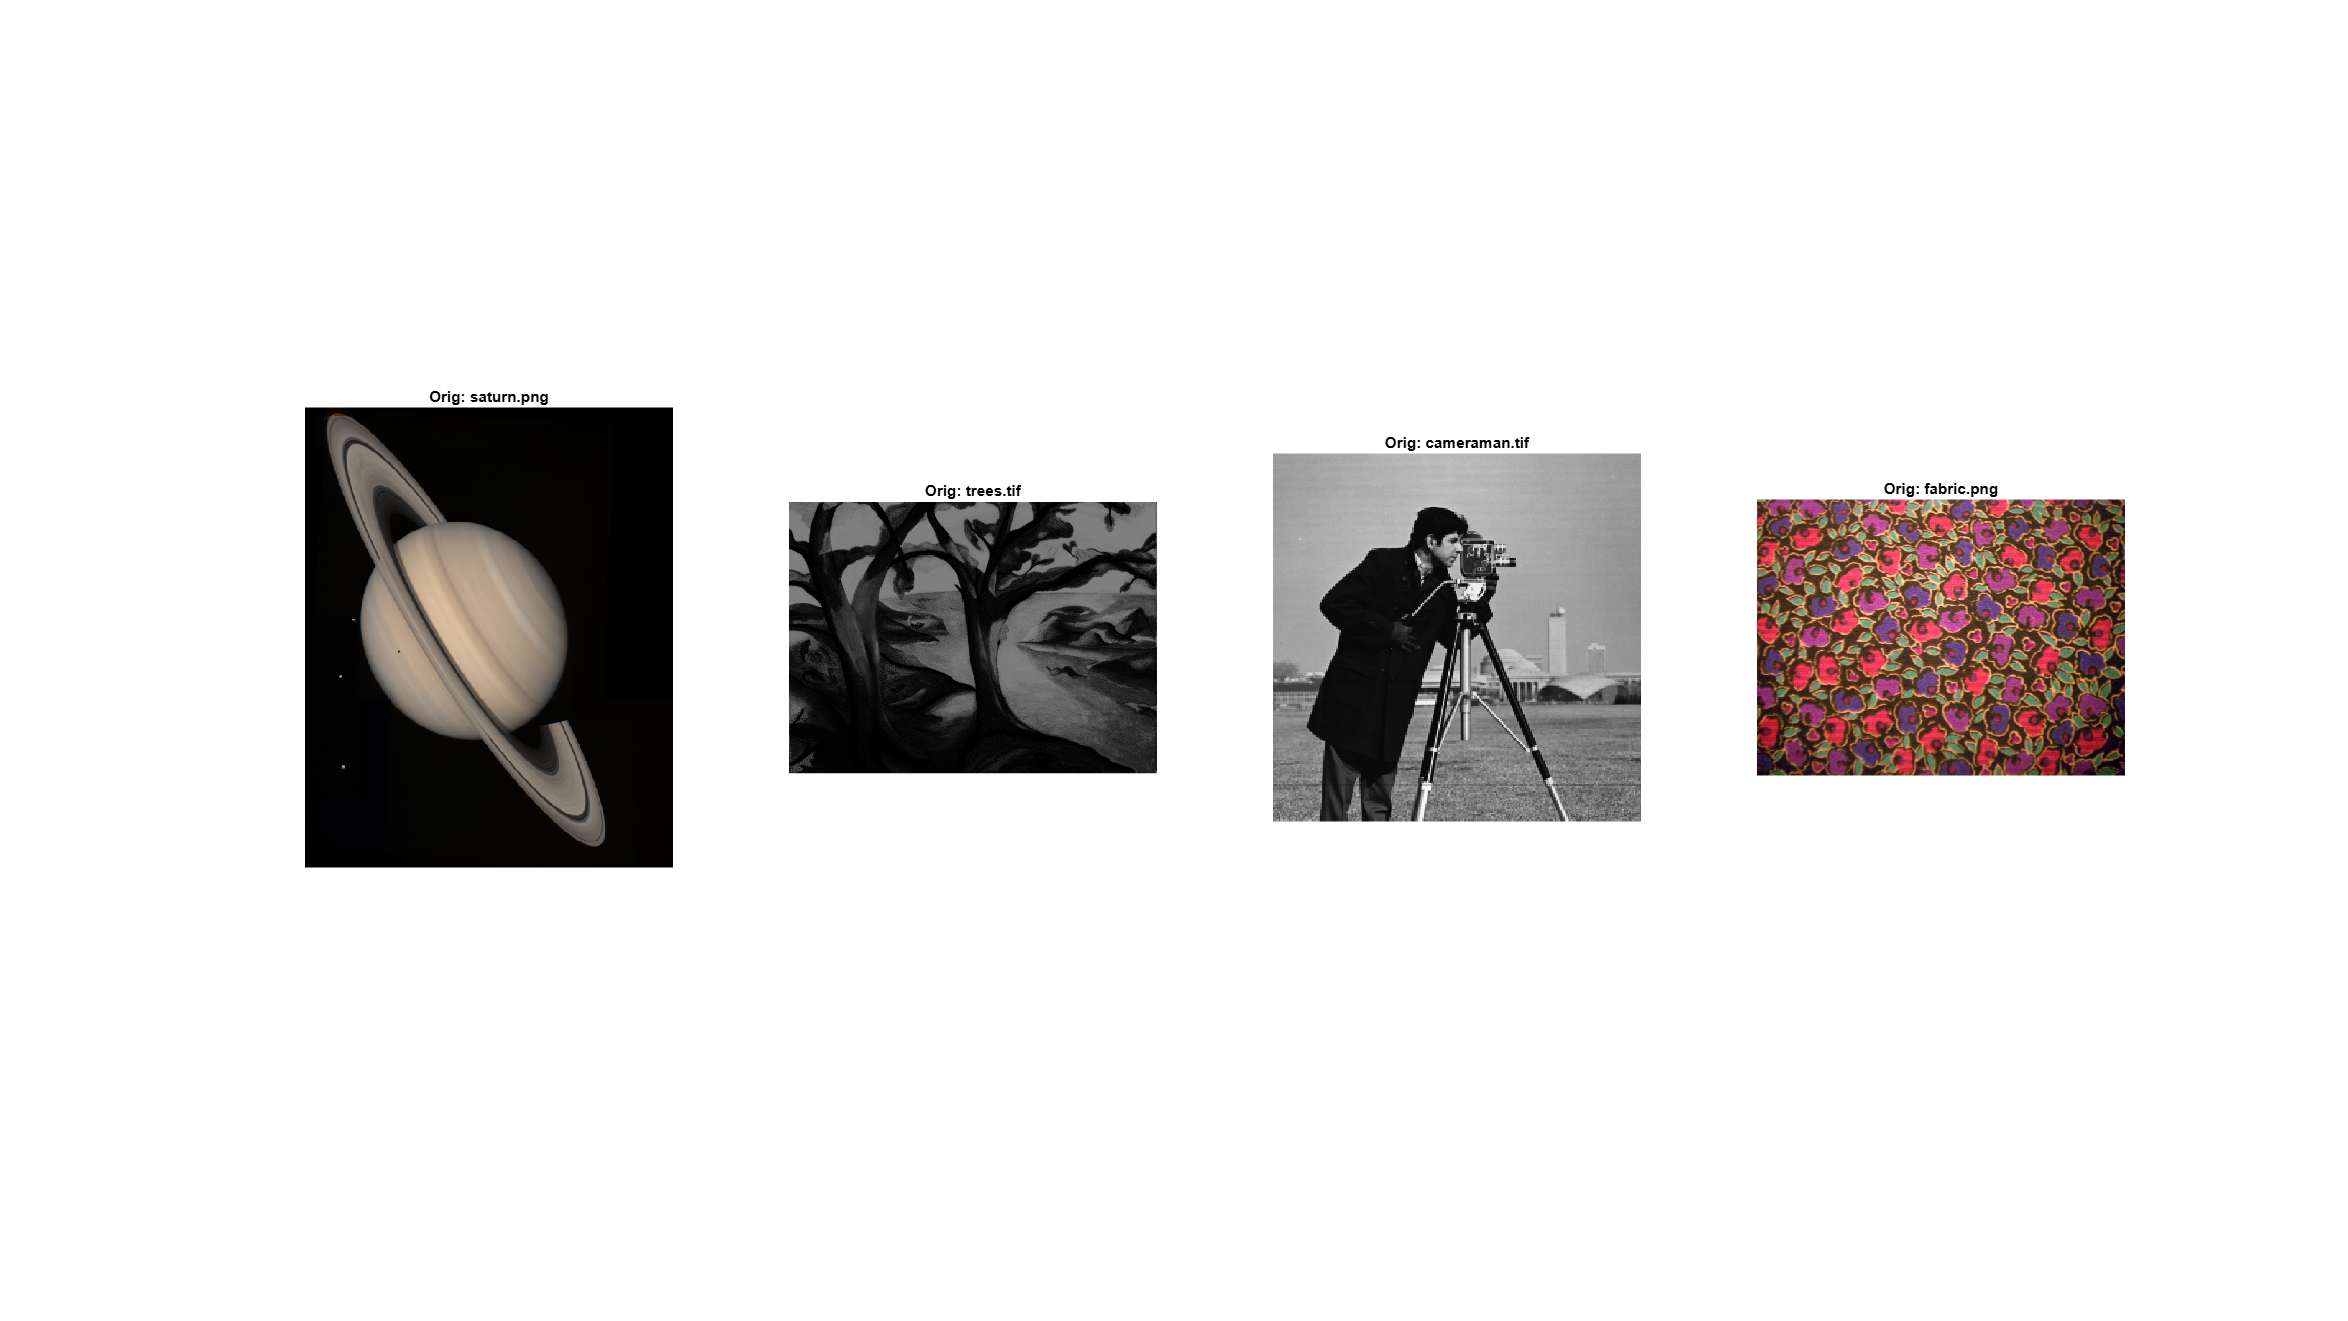

imgs = {'saturn.png', 'trees.tif', 'cameraman.tif', 'fabric.png'};

figure('Name','1. Початкові зображення','Units','normalized','OuterPosition',[0 0 1 1]);
for i = 1:numel(imgs)
    subplot(1,numel(imgs),i)
    I = imread(imgs{i});
    imshow(I,'InitialMagnification','fit')
    title(['Orig: ', imgs{i}],'Interpreter','none')
end

## 2. Конвертація в чорно-білий формат

grayImgs = cell(size(imgs));
for i = 1:numel(imgs)
    I = imread(imgs{i});
    if ndims(I) == 3
        grayImgs{i} = rgb2gray(I);
    else
        grayImgs{i} = I;
    end
end

## 3. Налаштування ДКП

N = 8;                   % розмір блоку
T = dctmtx(N);           % матриця ДКП
dct    = @(bs) T * double(bs.data) * T';  % пряма функція ДКП
invdct = @(bs) T' * bs.data * T;          % зворотна функція ДКП

% Опції для доповнення неповних блоків до 8×8
padOpts = {'PadPartialBlocks', true, 'PadMethod', 'symmetric'};

## 4-5. Поблочне ДКП із лог-шкалою та відновлення

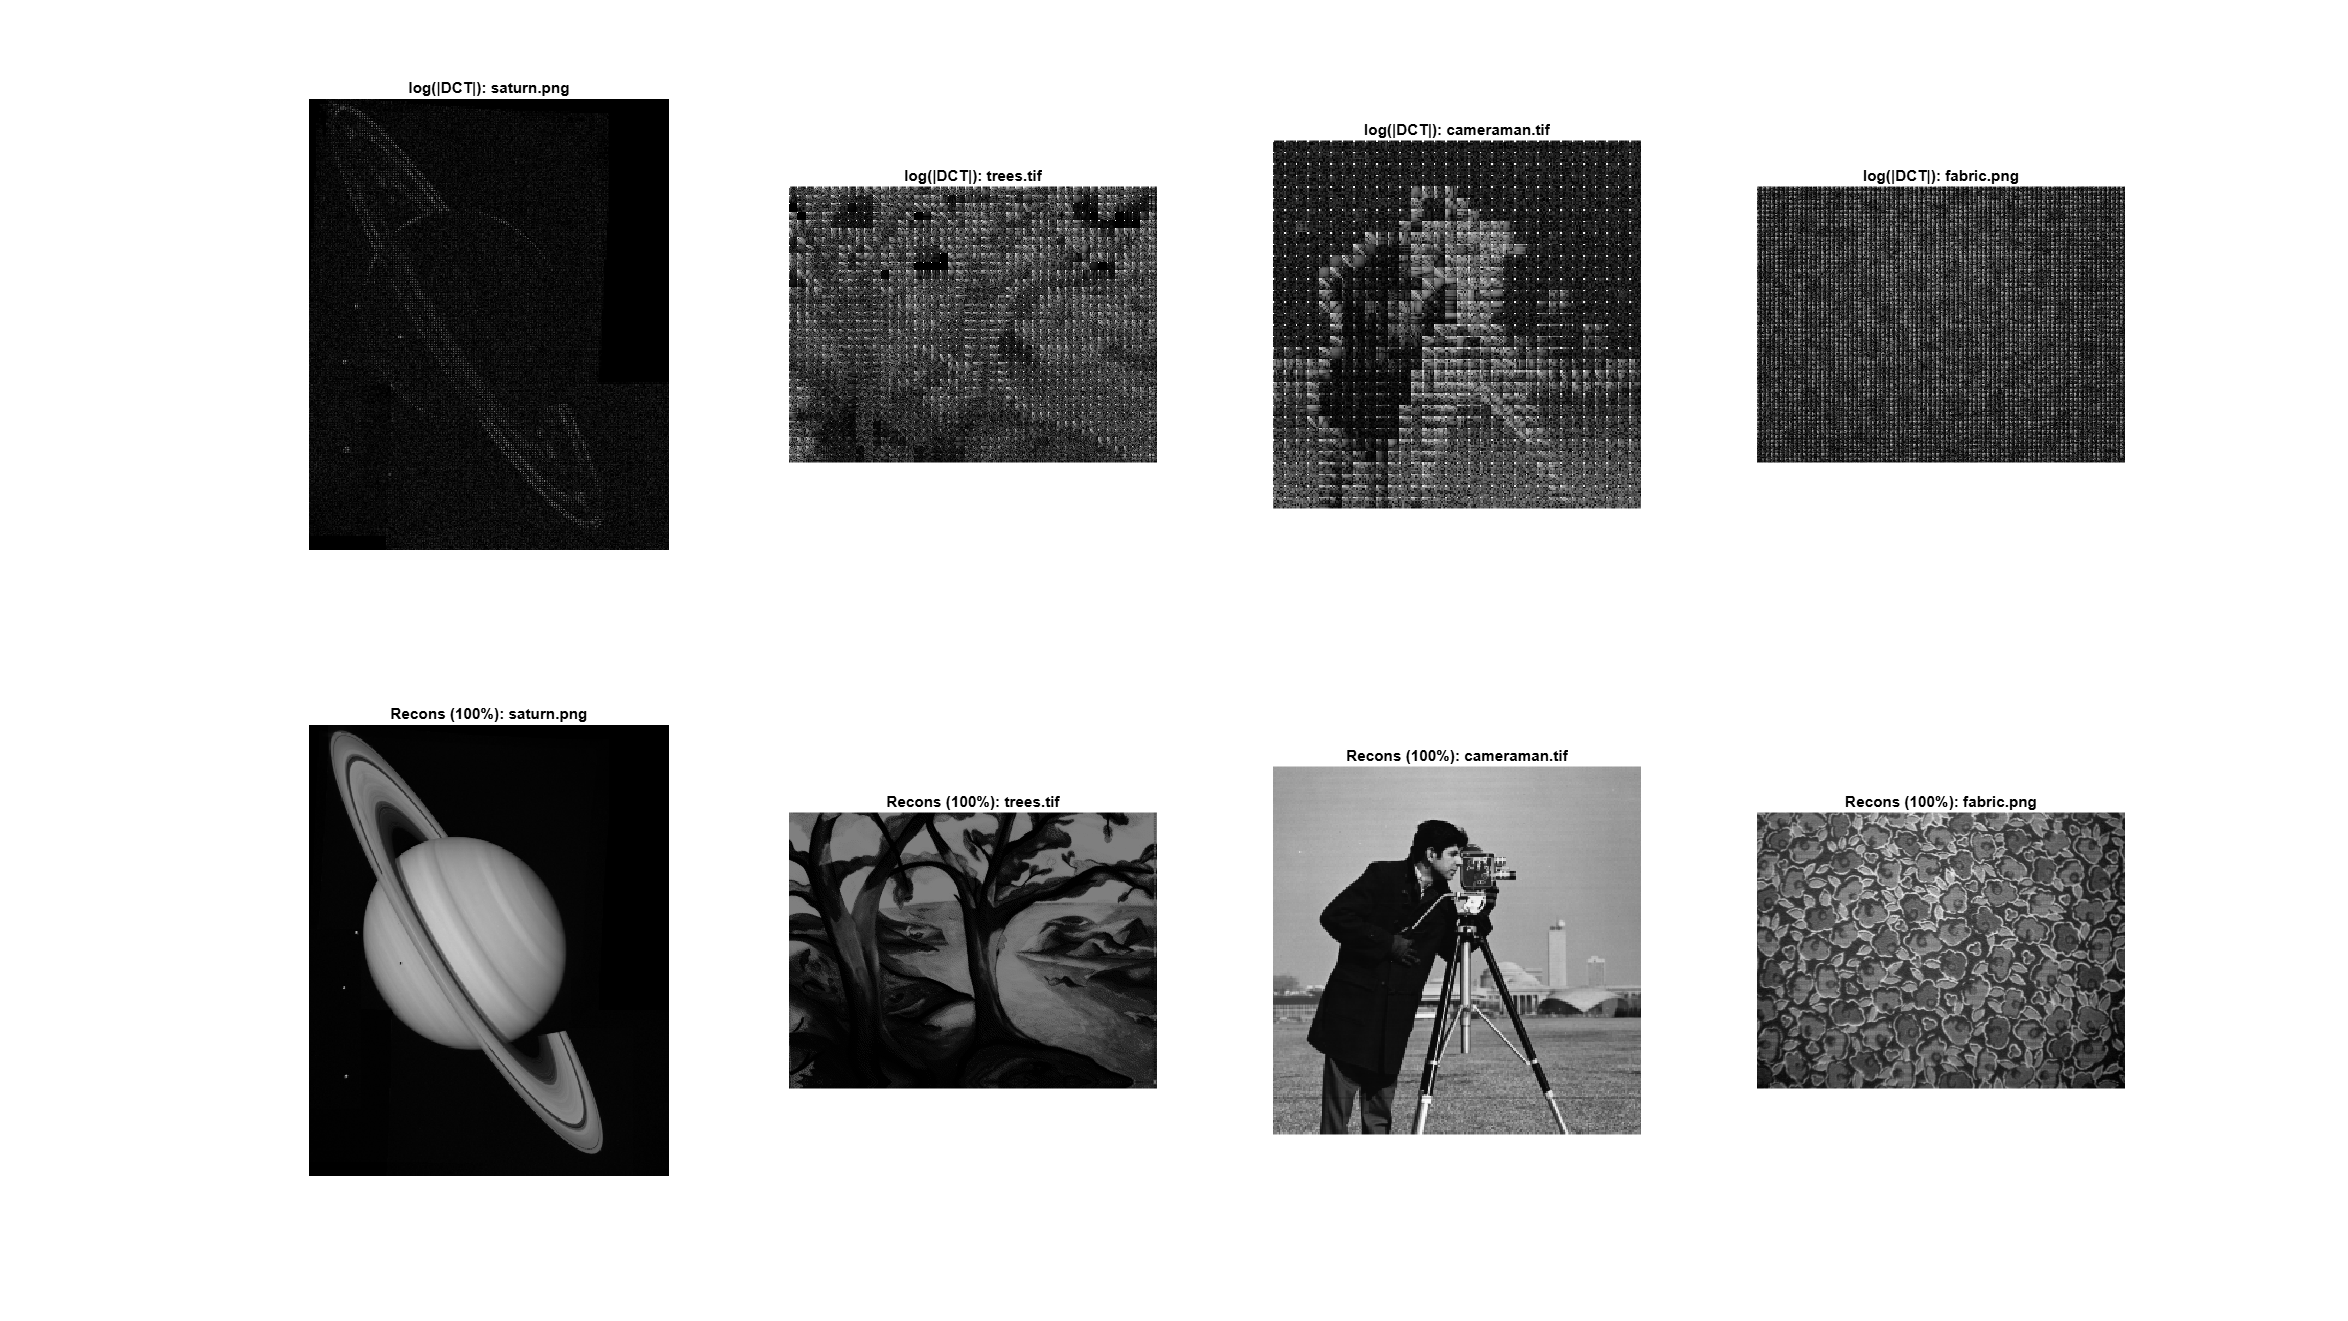

figure('Name','4–5. Поблочне ДКП та відновлення','Units','normalized','OuterPosition',[0 0 1 1]);
for i = 1:numel(grayImgs)
    B = grayImgs{i};
    % Поблочне ДКП
    D = blockproc(B, [N N], dct, padOpts{:});
    
    % Відображення спектра ДКП з логарифмічною шкалою
    subplot(2, numel(grayImgs), i)
    imshow(log(abs(D)+1), [], 'InitialMagnification','fit')
    title(['log(|DCT|): ', imgs{i}], 'Interpreter','none')
    
    % Відновлення зображення через зворотне ДКП
    Irec = uint8( blockproc(D, [N N], invdct, padOpts{:}) );
    subplot(2, numel(grayImgs), i+numel(grayImgs))
    imshow(Irec, 'InitialMagnification','fit')
    title(['Recons (100%): ', imgs{i}], 'Interpreter','none')
end

**log(|DCT|)** - це блокова мозаїка матриць ДКП (8 на 8) для кожного блоку вихідного зображення.

**Recons (100 %)** - це відновлене зображення після зворотного ДКП, коли ми не відкидаємо жодного коефіцієнта.

## 6. Квантування різними кроками q = [2, 5, 10]

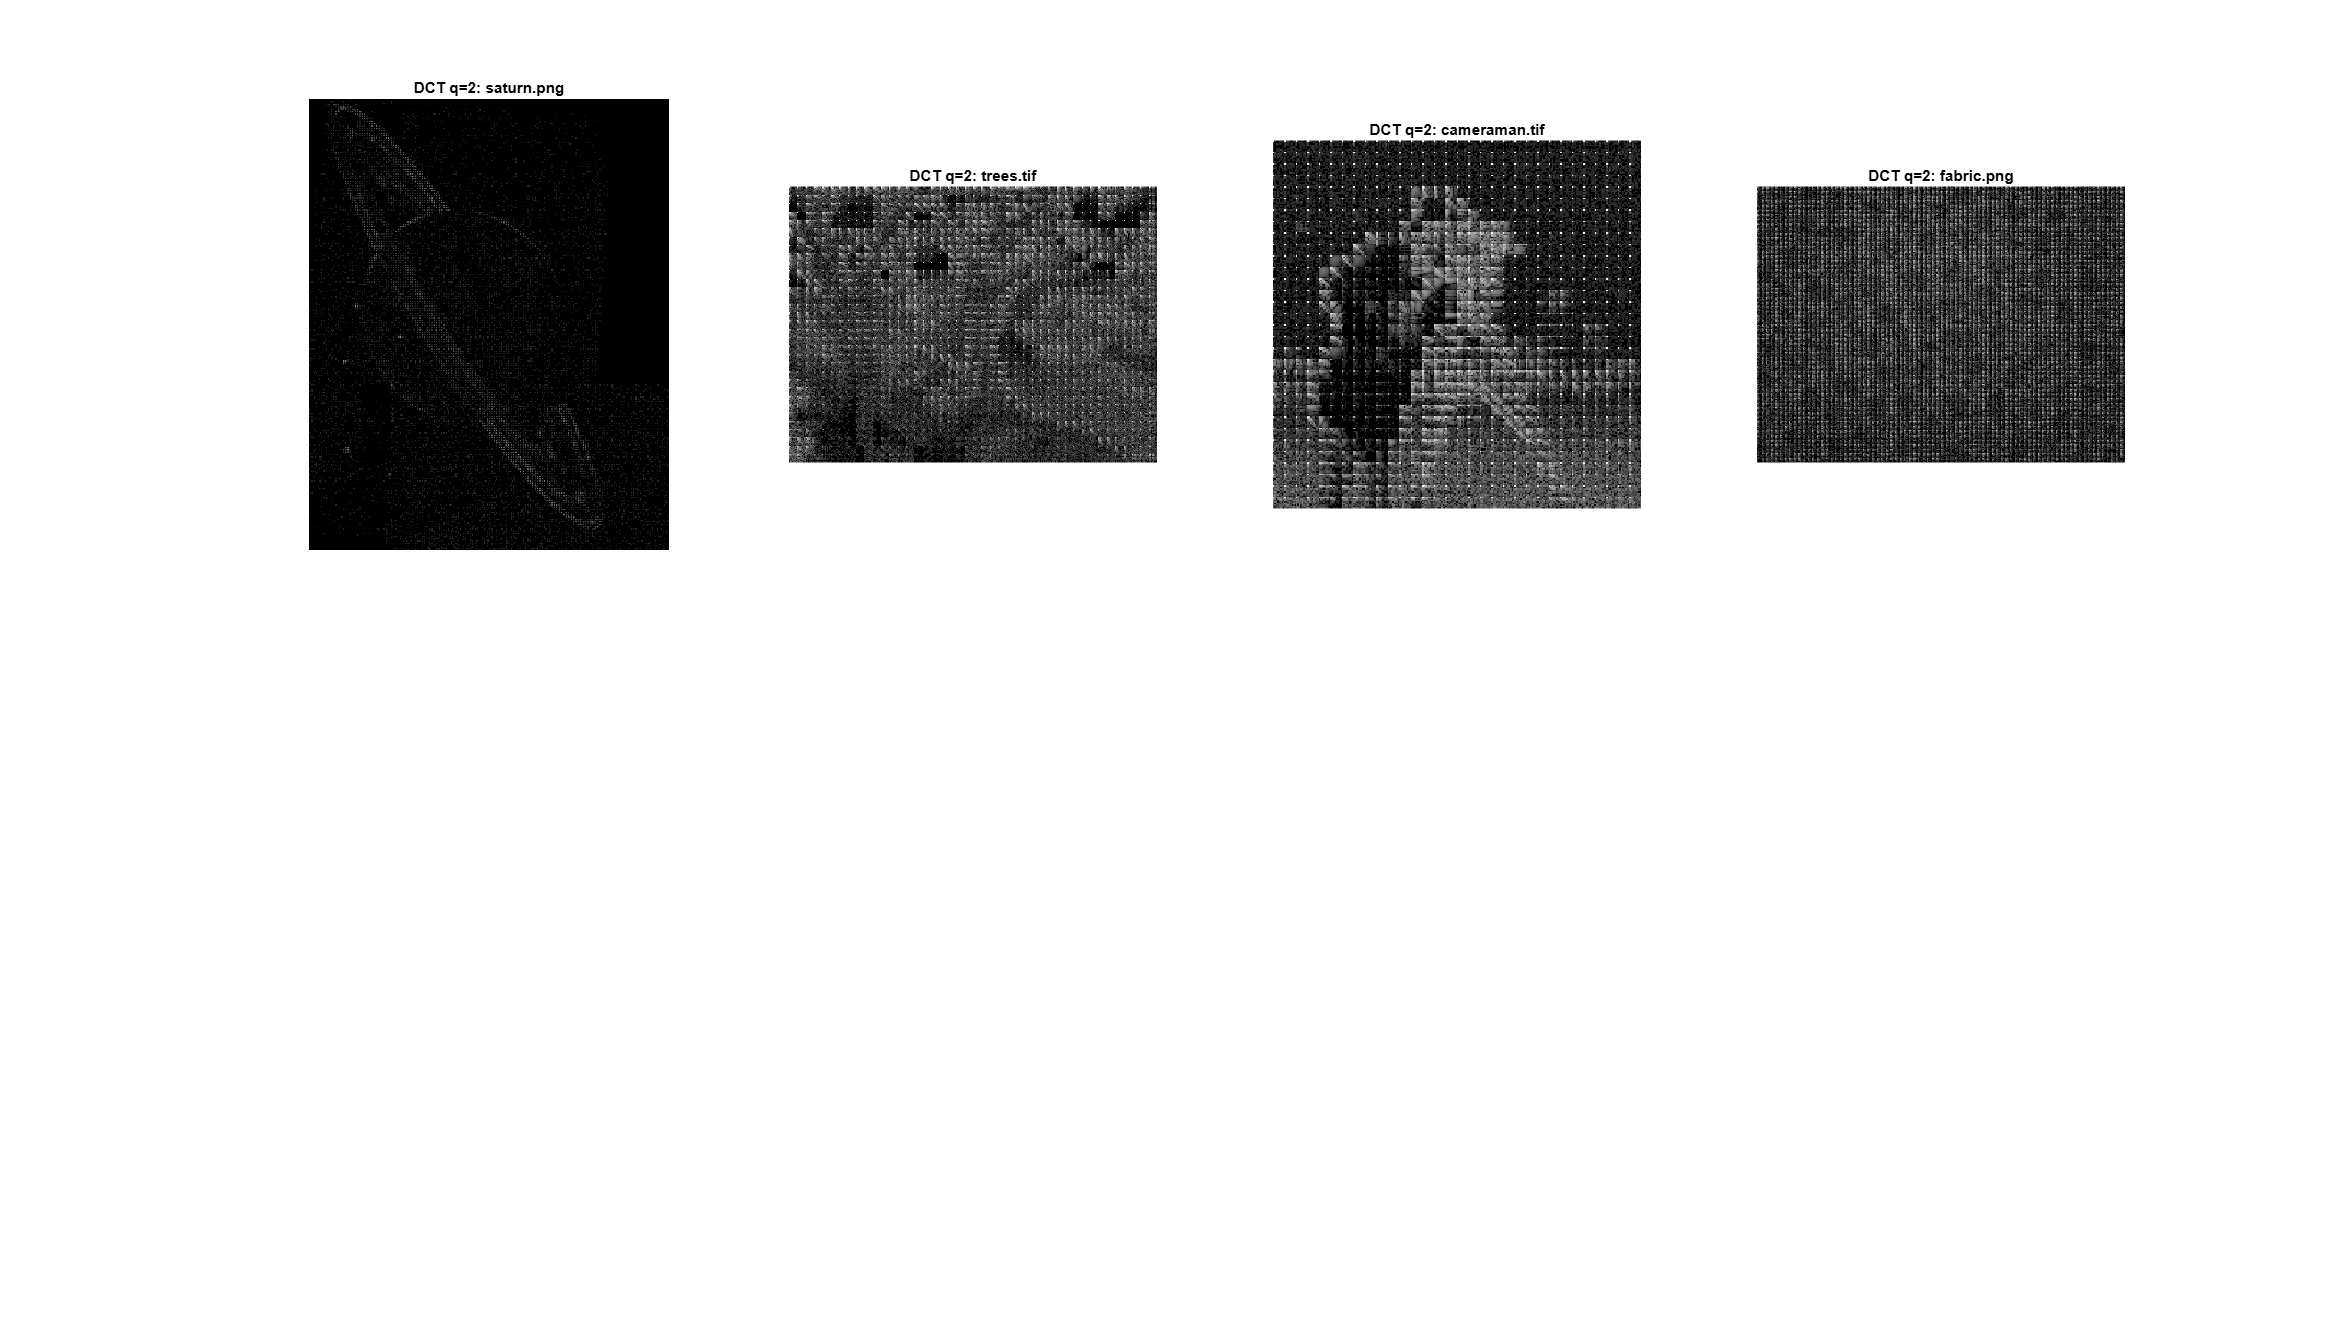

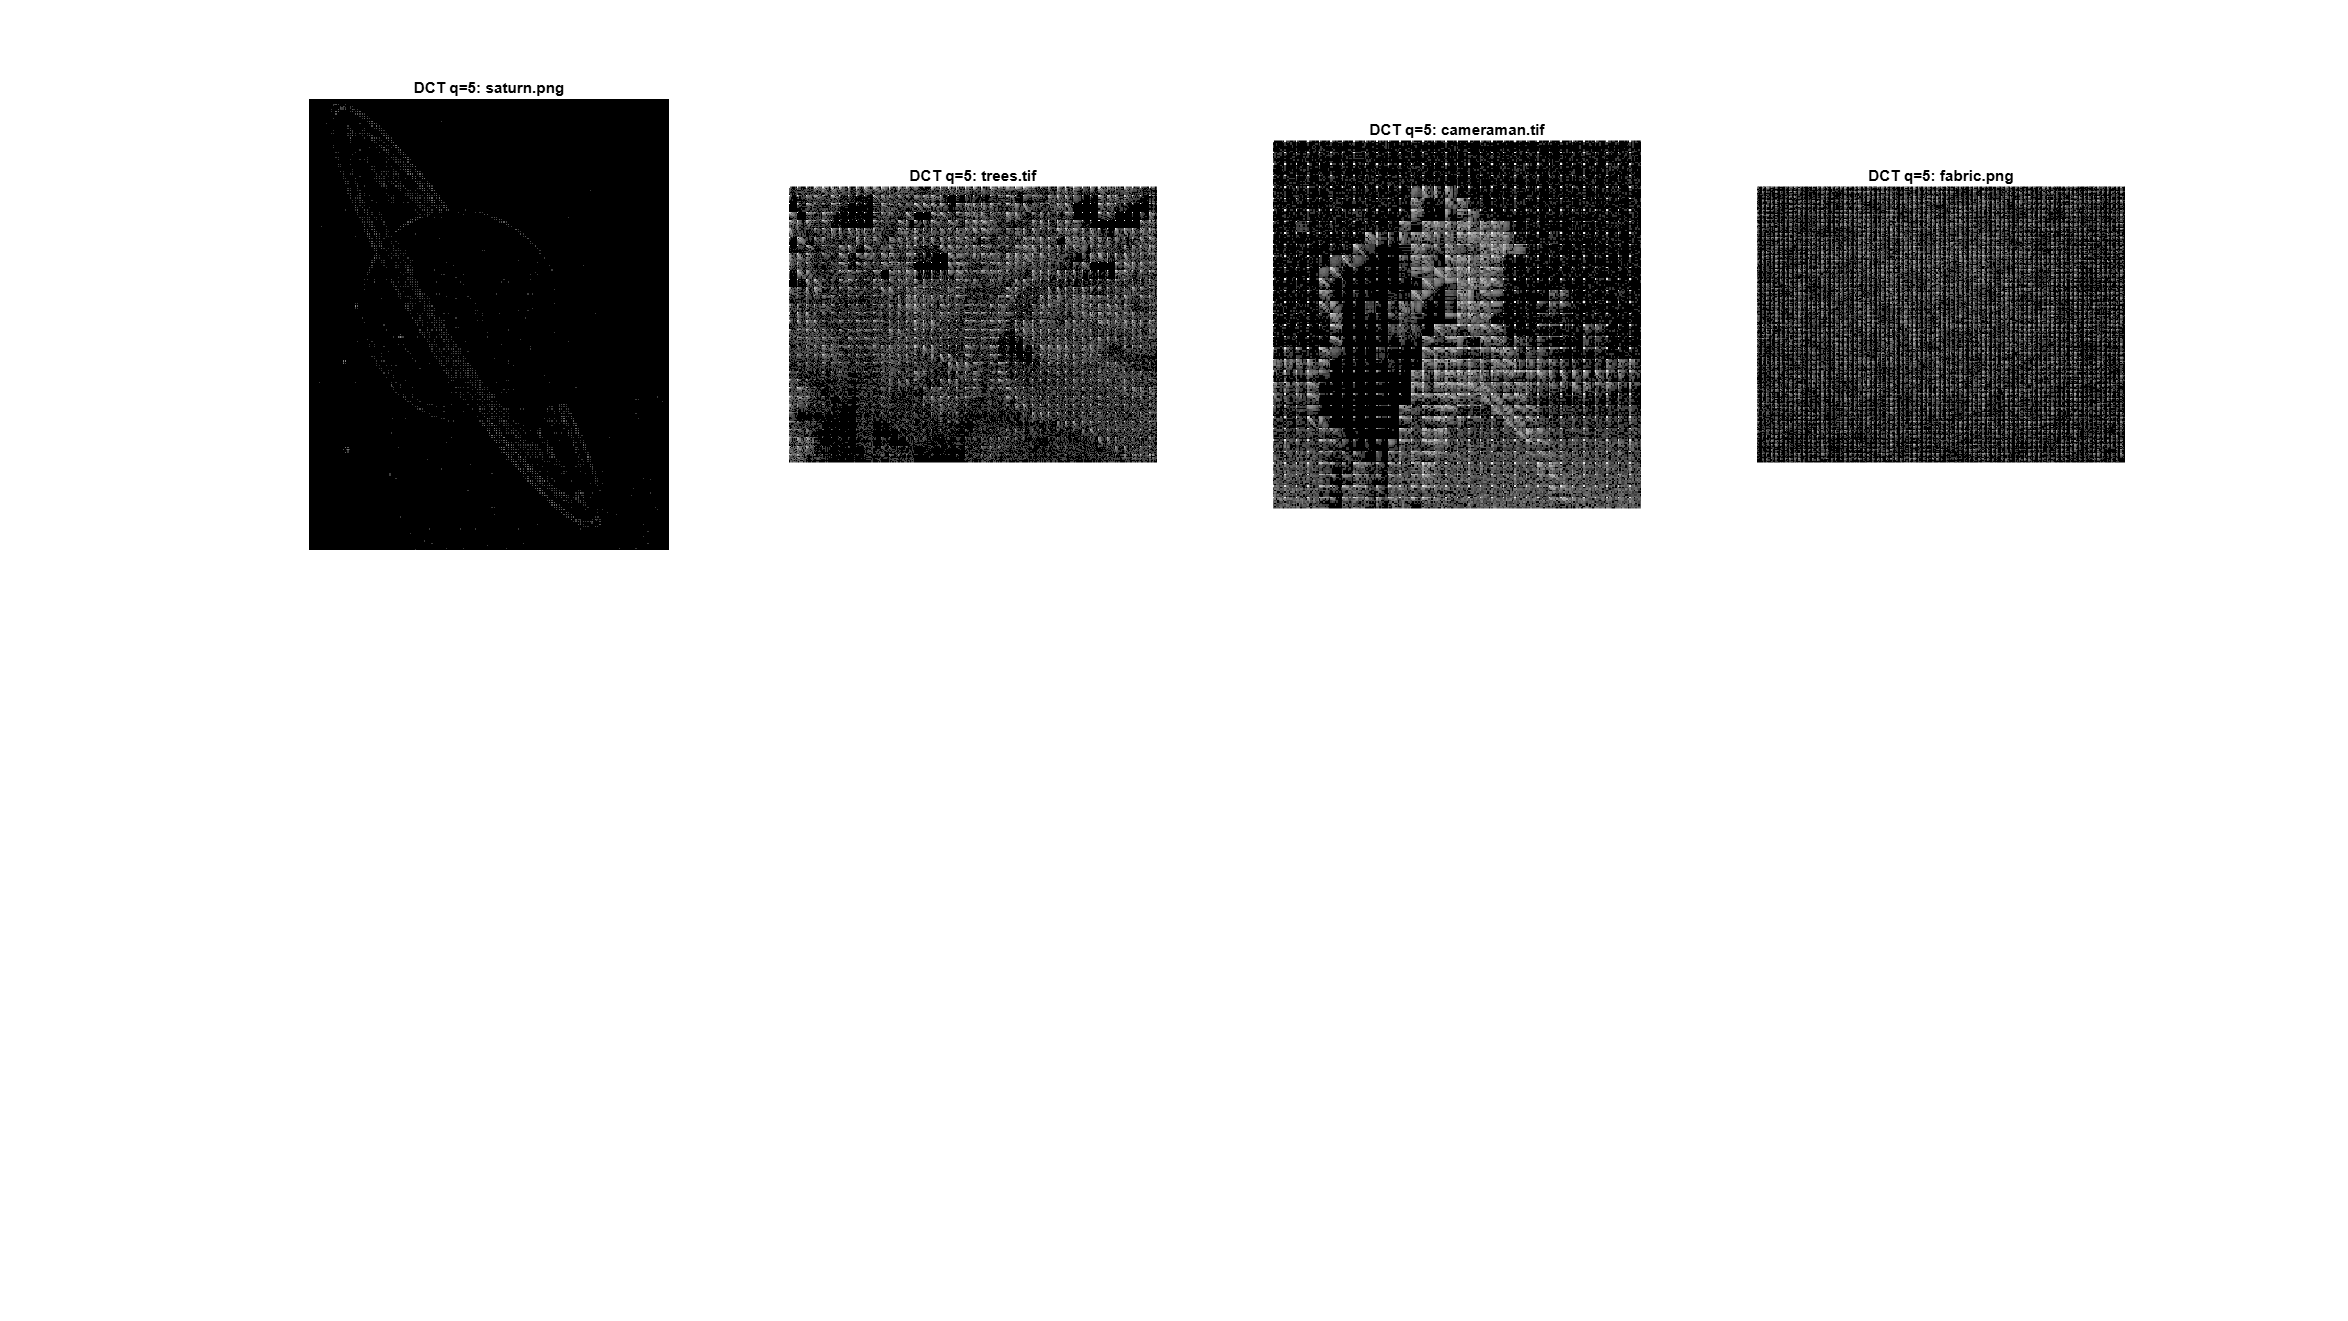

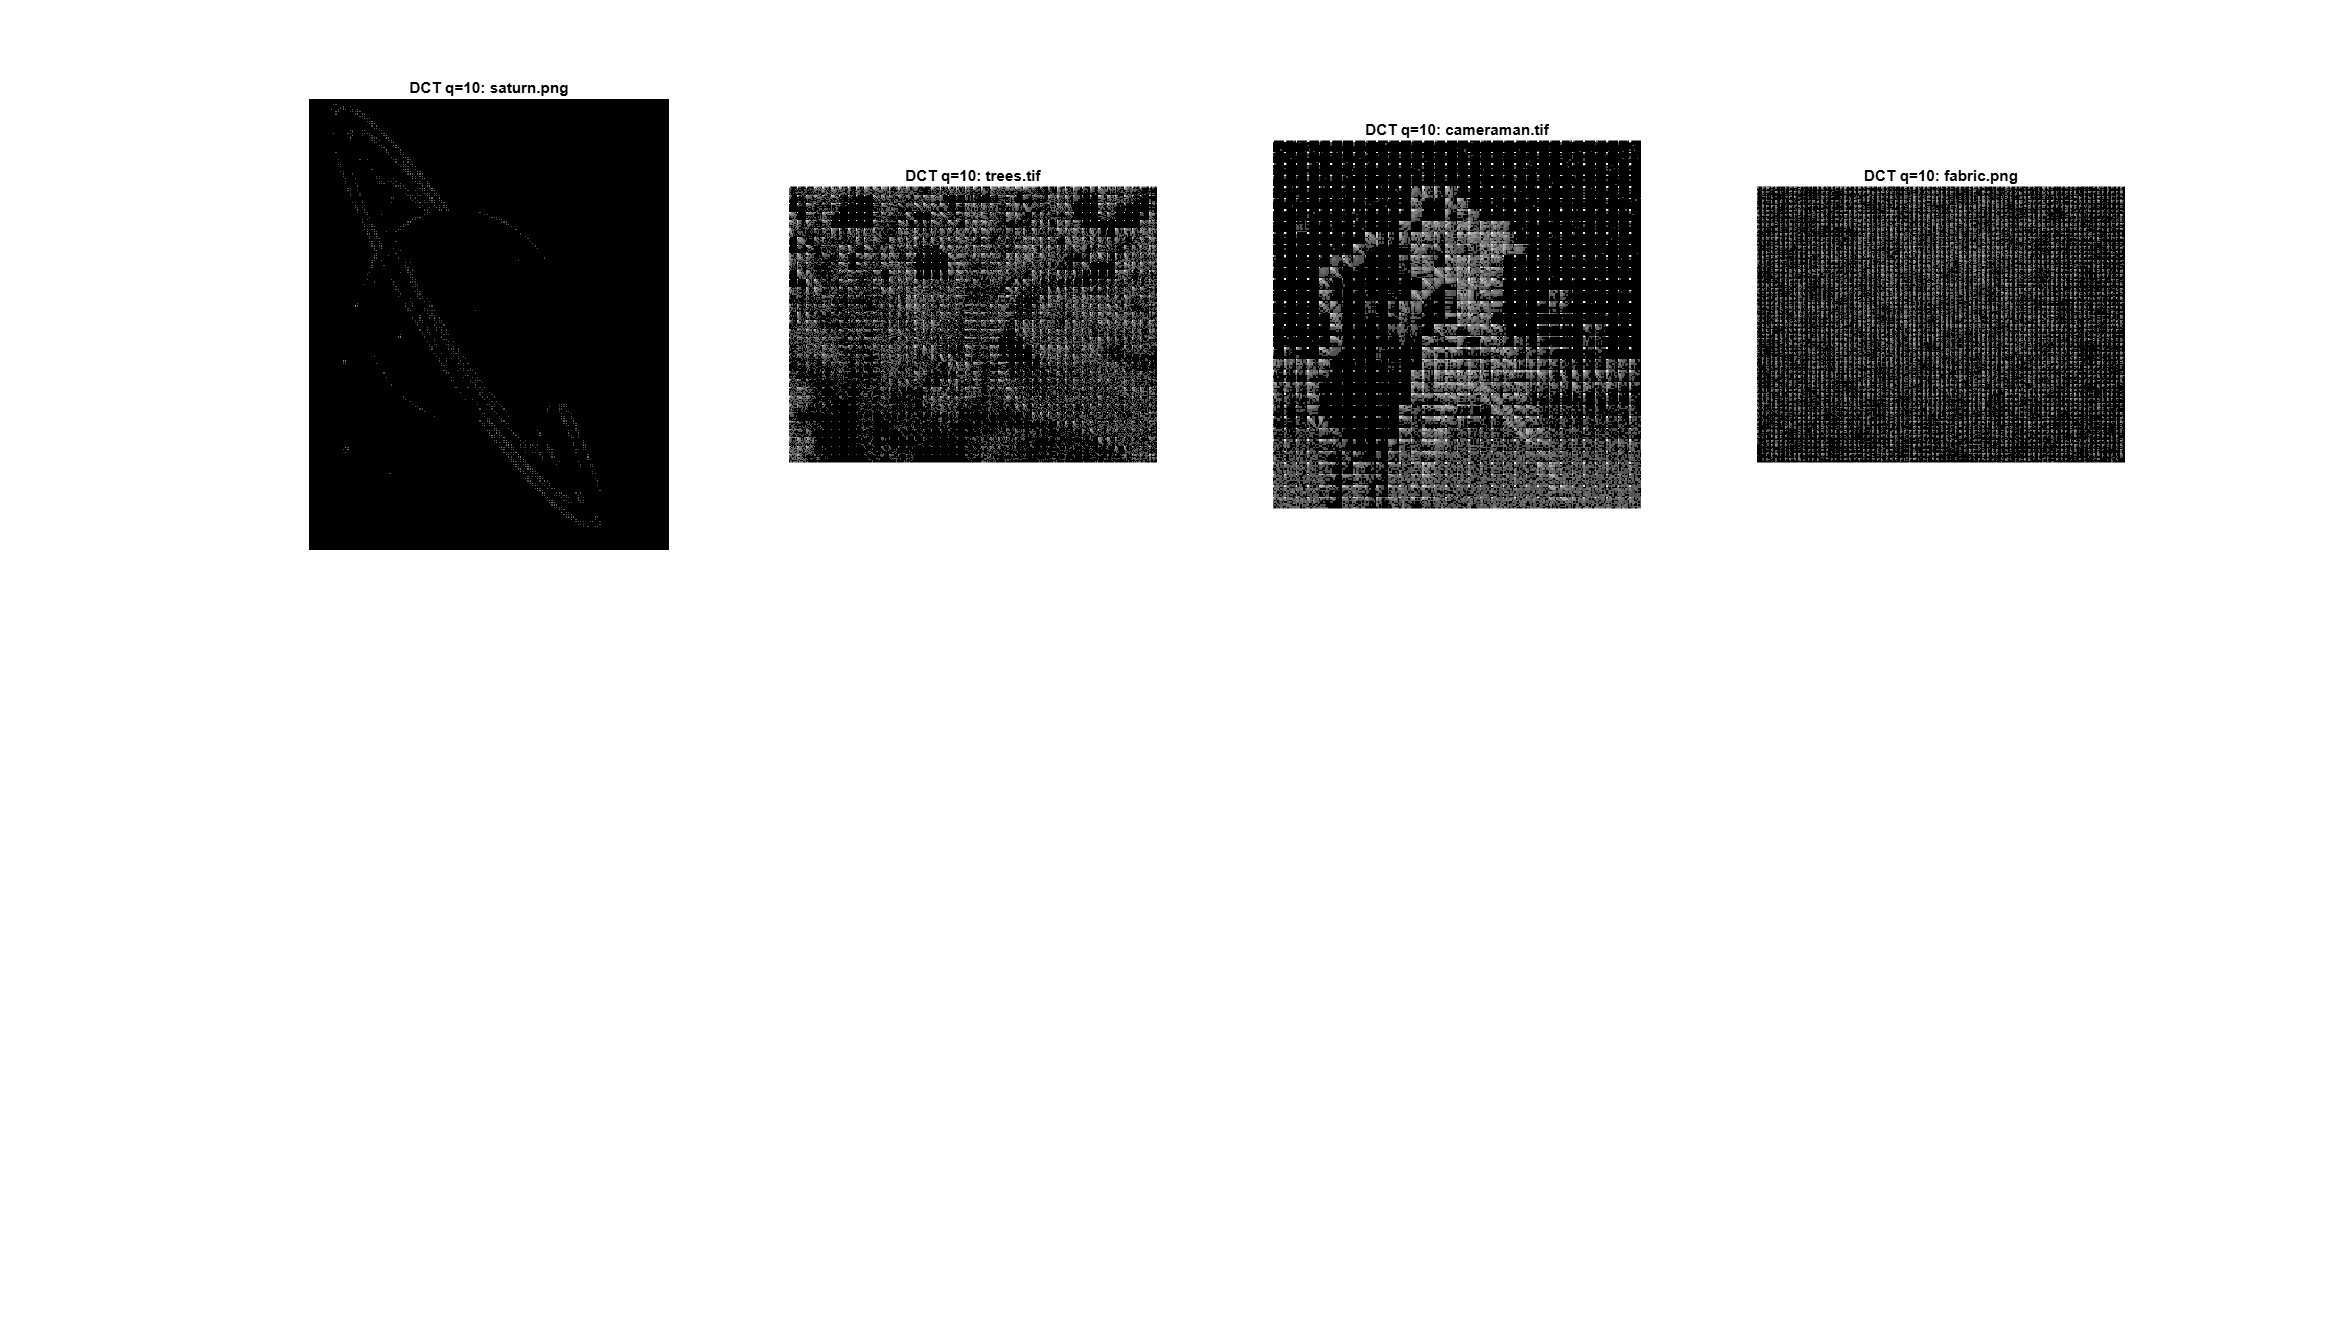

steps = [2, 5, 10];
for q = steps
    figure('Name',['6. Квантування q=',num2str(q)],'Units','normalized','OuterPosition',[0 0 1 1]);
    for i = 1:numel(grayImgs)
        B = grayImgs{i};
        % спочатку обчислюємо DCT-спектр
        D = blockproc(B, [N N], dct, padOpts{:});
        % Квантування
        Dq = blockproc(D, [N N], @(bs) q * round(bs.data / q), padOpts{:});
        
        % Відображення спектра після квантування
        subplot(2, numel(grayImgs), i)
        imshow(log(abs(Dq)+1), [], 'InitialMagnification','fit')
        title(['DCT q=',num2str(q),': ', imgs{i}], 'Interpreter','none')
        
        % Відновлення зображення зі спектра ДКП після квантування
        % Iq = uint8( blockproc(Dq, [N N], invdct, padOpts{:}) );
        %subplot(2, numel(grayImgs), i+numel(grayImgs))
        %imshow(Iq, 'InitialMagnification','fit')
        % title(['Recons q=',num2str(q),': ', imgs{i}], 'Interpreter','none')
    end
end

Чим менше q (наприклад, q=2) тим менше округлень і тим більше ненульових коефіцієнтів у кожному 8*8 блоці. Тому в лог-зображенні спектра помітні як низькі, так і середні/високі частоти.

Чим більше q (q=5, q=10) тим сильніше слабкі коефіцієнти округлюються до нуля. У спектрі залишається тільки найпотужніші спектри, решта блоку залишється темною.

Таким чином, збільшуючи q ми штучно стискаємо спектр, збільшуючи кількість нулів і зменшуючи деталізацію.

- **q=2**  легке квантування: високі частоти майже не змінені.

- **q=5**  середнє квантування: дрібні деталі (шум, текстури) зникають, але обриси основних форм зберігаються.

- **q=10**  сильне квантування: збережені тільки найбільш потужні низькі частоти, втрачені усі деталі, спектр дуже розріджений.

## 7-8. Квантування за маскою і відновлення

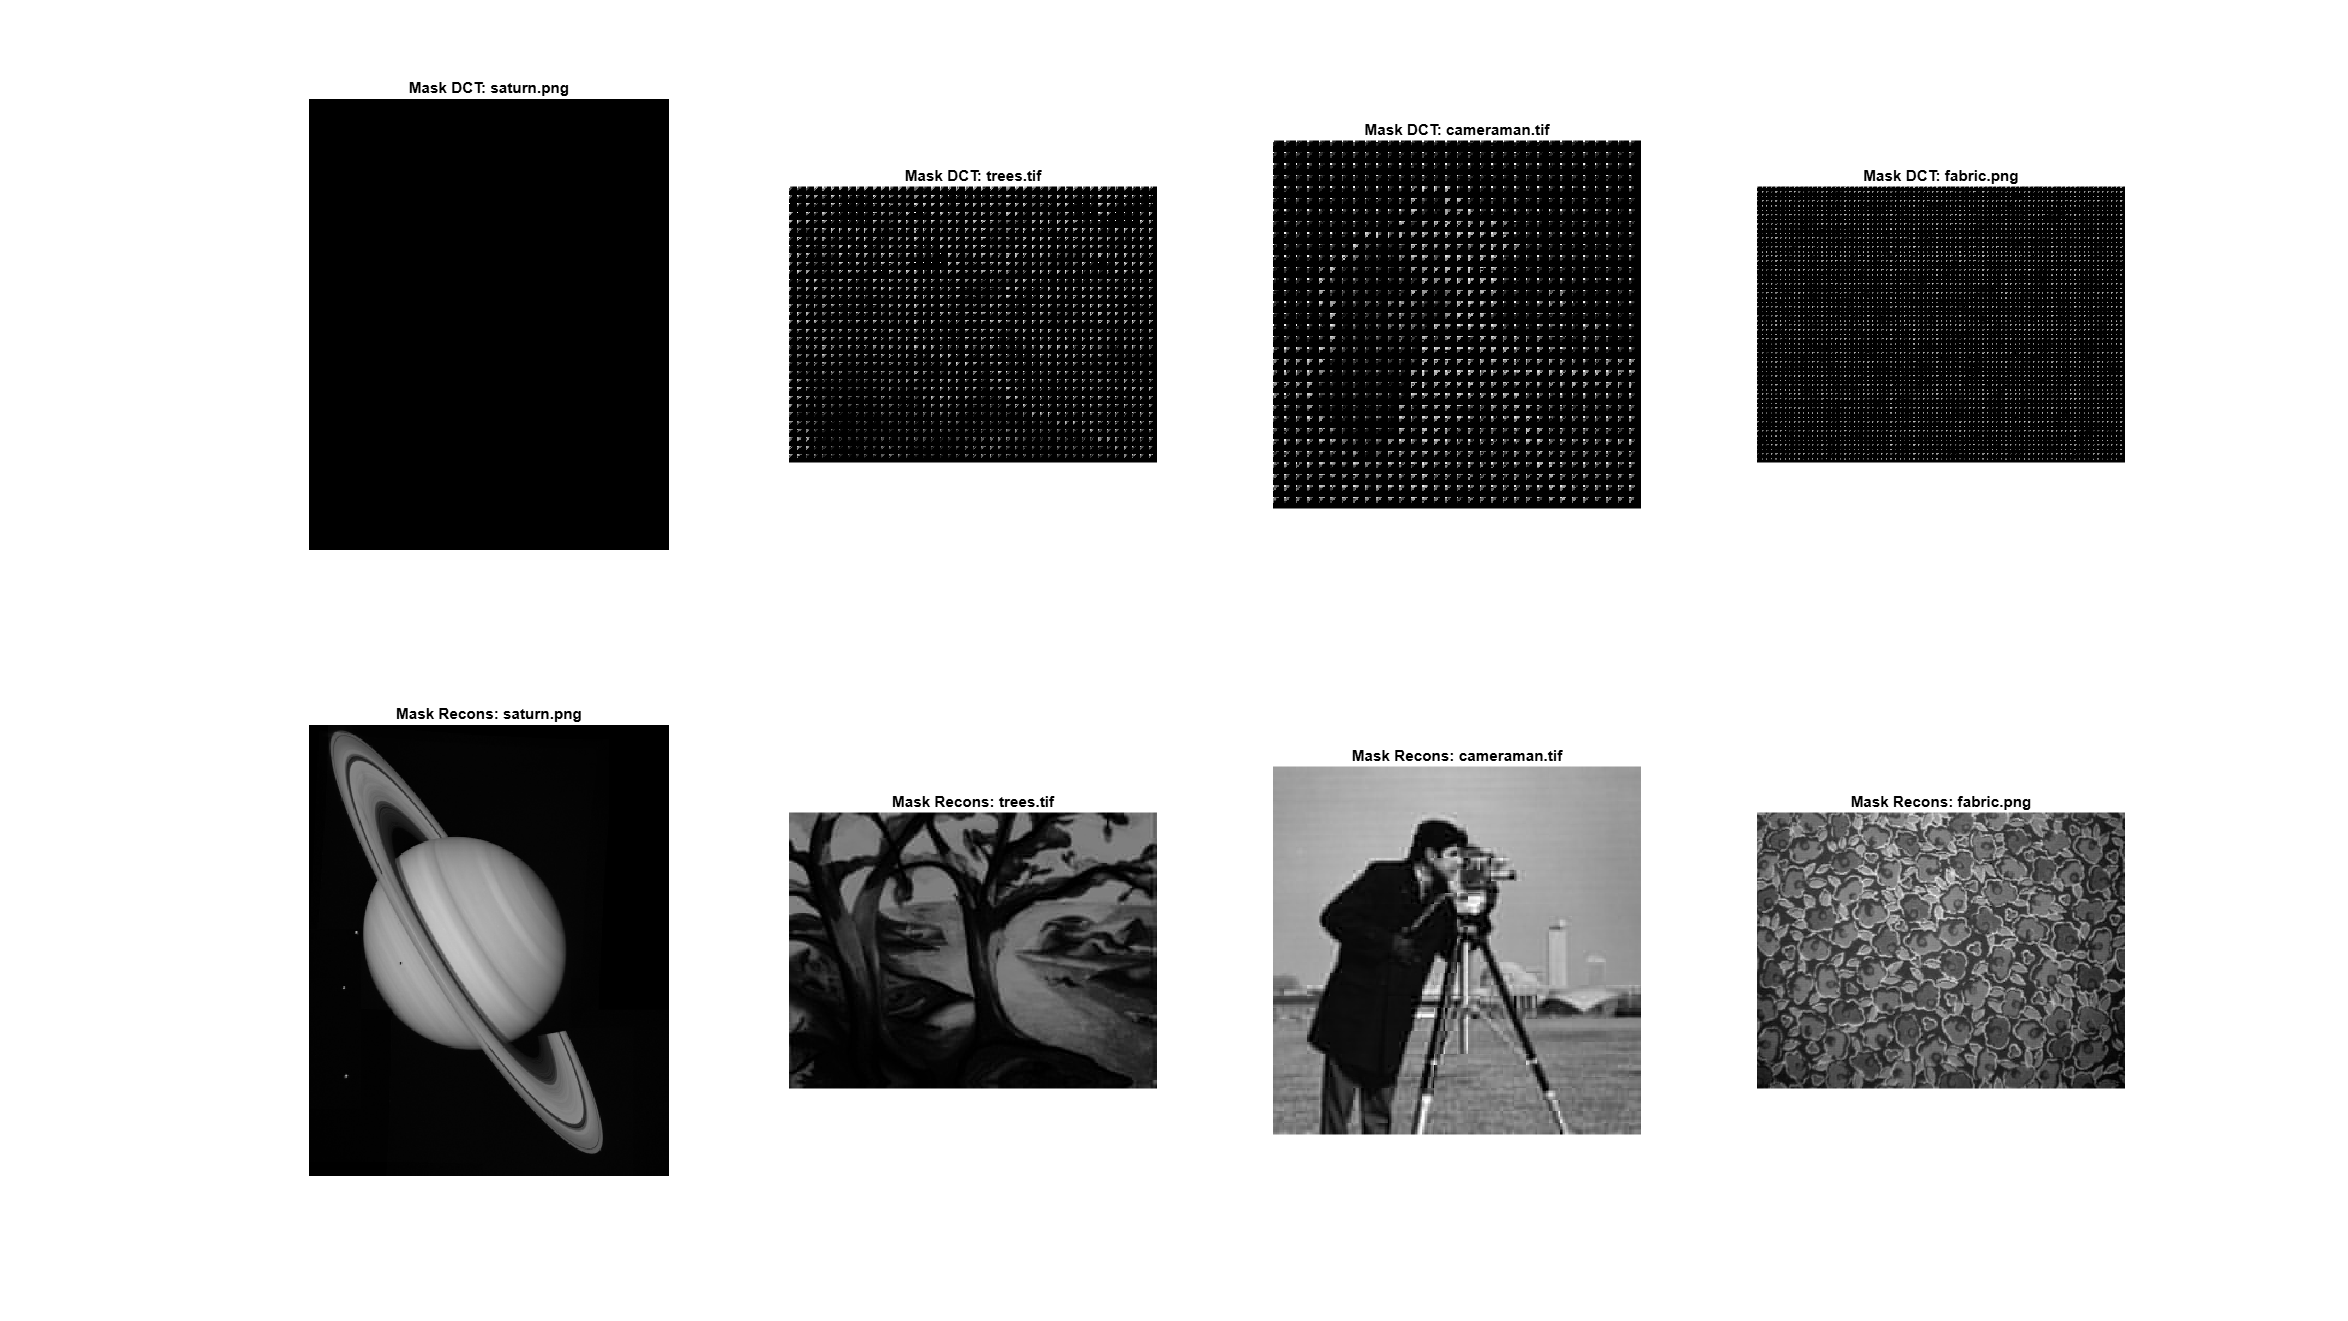

mask = [1 1 1 1 0 0 0 0;
        1 1 1 0 0 0 0 0;
        1 1 0 0 0 0 0 0;
        1 0 0 0 0 0 0 0;
        zeros(4,8)];
figure('Name','7-8. Квантування маскою та відновлення','Units','normalized','OuterPosition',[0 0 1 1]);
for i = 1:numel(grayImgs)
    B = grayImgs{i};
    D  = blockproc(B, [N N], dct, padOpts{:}); % DCT-спектр
    Dm = blockproc(D, [N N], @(bs) mask .* bs.data, padOpts{:});  % маска
    
    % Відображення спектра з маскою
    subplot(2, numel(grayImgs), i)
    imshow(log(abs(Dm)+1), [], 'InitialMagnification','fit')
    title(['Mask DCT: ', imgs{i}], 'Interpreter','none')
    
    % Відновлення після маски
    Icm = uint8( blockproc(Dm, [N N], invdct, padOpts{:}) );
    subplot(2, numel(grayImgs), i+numel(grayImgs))
    imshow(Icm, 'InitialMagnification','fit')
    title(['Mask Recons: ', imgs{i}], 'Interpreter','none')
end

**Загальні висновки по квантуванню з маскою та відновленню:**

- **Збереження низьких частот.** Маска залишає тільки перші 3-4 низькочастотні коефіцієнти в кожному блоці, тому при реконструкції відновлюються основні плавні переходи й контури.

- **Втрата дрібних деталей.** Все, що пов’язане з високими частотами обнуляється, зображення стає розмитим, без зернистих чи тонких структур.

- **Різниця між типами сцен.** Надгладкі сюжети (Saturn) майже не страждають: його форми добре описуються лише низькими частотами. А багаті на текстури зображення втрачають деталізацію.

## 9. Пояснення:

Квантуванням ДКП-коефіцієнтів, ми можемо досягти ефективного керованого стиснення зображення при мінімальному сприйманні втрат якості.

Також квантування ДКП-коефіцієнтів дозволяє:

- Знизити розрядність й обсяг даних

- Відкинути непомітні для ока деталі

- Контролювати співвідношення якості та розміру зображення